%Joseph Dearing
function tpair = pairtime(posa,vela,posb,velb,twosigma)
%taking inputs as 1x2 row vectors for postion and velocity
%need to input 2*sigma as sigma=r and collision occurs when positions are 
%2*r seperated 
del_x=[posa(1)-posb(1),posa(2)-posb(2)];
del_x_sq=del_x(1)^2+del_x(2)^2;
del_v=[vela(1)-velb(1),vela(2)-velb(2)];
del_v_sq=del_v(1)^2+del_v(2)^2;
scal=del_x(1)*del_v(1)+del_x(2)*del_v(2);
upsilon=scal^2-del_v_sq*(del_x_sq-4*twosigma^2);
if upsilon>0
    if scal<0
        tpair=-(scal+sqrt(upsilon))/del_v_sq;
    else
        tpair=inf;
    end
else
    tpair=inf;
end
end

function twall = walltime(posa,vela,sigma)
%all inputs taken as integers, hence in eventdisks we need to consider x
%and y wall collisions
if vela>0
   twall=(1-posa-sigma)/vela;
elseif vela<0
    twall=(posa-sigma)/abs(vela);
else
    twall = inf;
end
end

function eventdisks(pos,vel,sigma,N,n_events)
t=0;
walltimes=zeros(1,2*N);
pairs=nchoosek(1:N,2);%create all possible pairs for N disks
pairtimes=zeros(1,nchoosek(N,2));
t_sample=0;
dt=0.1; %seperation of time for which we take samples
%optimising code with preallocation as it was running slowly
est_length=n_events*20*N; 
x_history=zeros(est_length,1);
c=1;
for i = 1:n_events
    %computing all wall collision times
    for j =1:N
        walltimes(j)=walltime(pos(j,1),vel(j,1),sigma/2);   
        walltimes(j+N)=walltime(pos(j,2),vel(j,2),sigma/2);
    end
    %computing all pair collision times
    for k=1:nchoosek(N,2)
        pairtimes(k)=pairtime(pos(pairs(k,1),:),vel(pairs(k,1),:), ...
            pos(pairs(k,2),:),vel(pairs(k,2),:),sigma);
    end
    %determining event at with least time to occur
    [m_w,w_i]=min(walltimes);
    [m_p,p_i]=min(pairtimes);
    if m_w<m_p
            m=m_w;
            event_type = 'wall';
            mindex = w_i;
    else
            m=m_p;
            event_type = 'pair';
            mindex = p_i;
    end
    %recording values of x up until time of collision
    while t_sample < (t + m)
        pos_at_sample = pos + vel * (t_sample - t);
        %more optimisation
        if c+N > length(x_history)
            x_history(end + 100000) = 0; 
        end
        x_history(c:c+N-1)=pos_at_sample(:,1);
        c=c+N;
        t_sample=t_sample+dt;      
    end
    %updating time and position
    t=t+m;
    pos=pos+vel*m;
    %updating velocity dependant on which collision occurs
    if strcmp(event_type,'wall')
        %collision with wall x or y reverses direction of velocity of disk 
        %in x or y
        if mindex<=N
            vel(mindex,1)=-1*vel(mindex,1);
        else
            vel(mindex-N,2)=-1*vel(mindex-N,2);
        end
    else
        pair=pairs(mindex,:);
        del_x=[pos(pair(1),1)-pos(pair(2),1),pos(pair(1),2)-pos(pair(2),2)];
        abs_x=sqrt(del_x(1)^2+del_x(2)^2);
        e_perp=del_x/abs_x;
        del_v=[vel(pair(1),1)-vel(pair(2),1),vel(pair(1),2)-vel(pair(2),2)];
        vel(pair(1),:)=vel(pair(1),:)-e_perp*(dot(del_v,e_perp));
        vel(pair(2),:)=vel(pair(2),:)+e_perp*(dot(del_v,e_perp));
    end
end
x_history = x_history(1:c-1);
histogram(x_history,"BinLimits",[0.075,0.925],"NumBins",50,'Normalization','pdf');
title(['N=',num2str(N),',Sigma=',num2str(sigma)]);
xlabel('x position');
ylabel('Probability Density');
xlim([0, 1]);
end

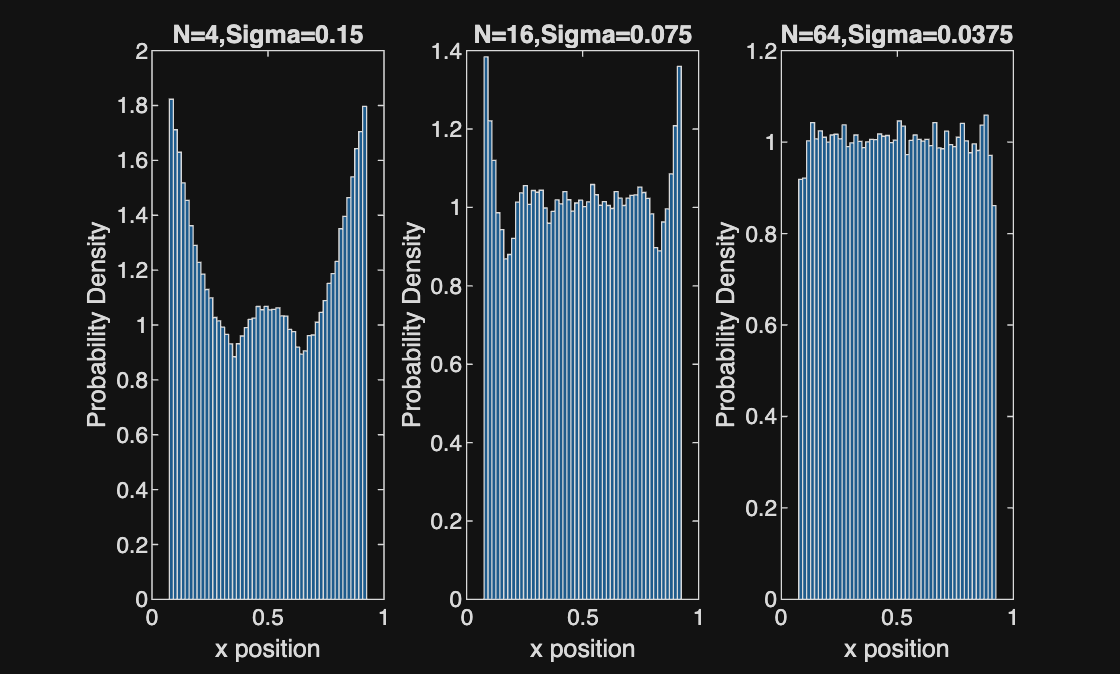

Nlist=[4,16,64];
sigma_og=0.15;
N_og=4;
n_events=100000;
figure;
for i=1:length(Nlist)
    N=Nlist(i);
    %scaling sigma so density remains the same
    %N1*pi*sigma1^2=N2*pi*sigma2^2
    sigma=sigma_og*sqrt(N_og/N);
    %spacing disks evenly across sqaure at t=0
    side=ceil(sqrt(N));
    spacing=1/(side+1);
    [X,Y]=meshgrid(spacing:spacing:1-spacing);
    pos=[X(:),Y(:)];
    pos=pos(1:N,:); 
    %choosing veloctiy to be rand(-1,1)
    vel=2*rand(N,2)-1;
    subplot(1,3,i);
    eventdisks(pos,vel,sigma,N,n_events);
end

We can see that for N=4 we recover the "Batman" density. Futhermore, by increasing N we can see that the features of the "Batman" flaten out. When N=4 due to the size of the disks, they struggle to form a uniform "fliud" in the middle.However, after increasing N sufficiently the phenomanon becomes less prevalent and the disks form a more uniform "fluid".

function eventdiskvel(pos,vel,sigma,N,n_events)
%modified code to sample velocity, and plot such with guassian overlay
t=0;
walltimes=zeros(1,2*N);
pairs=nchoosek(1:N,2);
pairtimes=zeros(1,nchoosek(N,2));
t_sample=0;
dt=0.1;
est_length=n_events*10; 
vx_history=zeros(est_length,1);
c=1;
for i = 1:n_events
    for j =1:N
        walltimes(j)=walltime(pos(j,1),vel(j,1),sigma/2);   
        walltimes(j+N)=walltime(pos(j,2),vel(j,2),sigma/2);
    end
    for k=1:nchoosek(N,2)
        pairtimes(k)=pairtime(pos(pairs(k,1),:),vel(pairs(k,1),:), ...
            pos(pairs(k,2),:),vel(pairs(k,2),:),sigma);
    end
    [m_w,w_i]=min(walltimes);
    [m_p,p_i]=min(pairtimes);
    if m_w<m_p
            m=m_w;
            event_type = 'wall';
            mindex = w_i;
    else
            m=m_p;
            event_type = 'pair';
            mindex = p_i;
    end
    while t_sample<t+m
        if c>length(vx_history)
            vx_history(end+10000)=0;
        end
        vx_history(c)=vel(1,1);
        c=c+1;
        t_sample=t_sample+dt;
    end
    t=t+m;
    pos=pos+vel*m;
    if strcmp(event_type,'wall')
        if mindex<=N
            vel(mindex,1)=-1*vel(mindex,1);
        else
            vel(mindex-N,2)=-1*vel(mindex-N,2);
        end
    else
        pair=pairs(mindex,:);
        del_x=[pos(pair(1),1)-pos(pair(2),1),pos(pair(1),2)-pos(pair(2),2)];
        abs_x=sqrt(del_x(1)^2+del_x(2)^2);
        e_perp=del_x/abs_x;
        del_v=[vel(pair(1),1)-vel(pair(2),1),vel(pair(1),2)-vel(pair(2),2)];
        vel(pair(1),:)=vel(pair(1),:)-e_perp*(dot(del_v,e_perp));
        vel(pair(2),:)=vel(pair(2),:)+e_perp*(dot(del_v,e_perp));
    end
end
vx_history=vx_history(1:c-1);
mu=mean(vx_history);
sd=std(vx_history);
x=linspace(min(vx_history),max(vx_history),100);
y=1/(sd*sqrt(2*pi))*exp(-0.5*((x-mu)/sd).^2);
hold on;
histogram(vx_history,50,'Normalization','pdf');
plot(x,y,'r','LineWidth',2)
title(['N=',num2str(N),',Sigma=',num2str(sigma)]);
xlabel('Velocity in x of disk 1');
ylabel('Probability Density');
hold off;
end

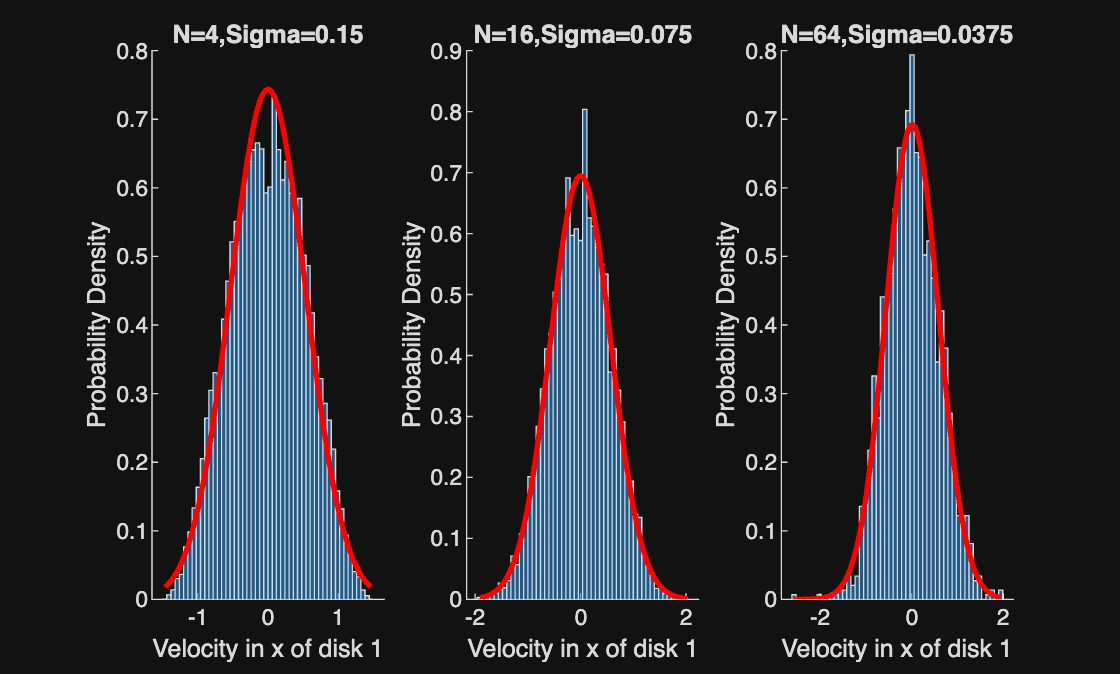

Nlist=[4,16,64];
sigma_og=0.15;
N_og=4;
n_events=100000;
figure;
for i=1:length(Nlist)
    N=Nlist(i);
    sigma=sigma_og*sqrt(N_og/N);
    side=ceil(sqrt(N));
    spacing=1/(side+1);
    [X,Y]=meshgrid(spacing:spacing:1-spacing);
    pos=[X(:),Y(:)];
    pos=pos(1:N,:); 
    vel=2*rand(N,2)-1;
    subplot(1,3,i);
    eventdiskvel(pos,vel,sigma,N,n_events);
end

By initialising the velocity as rand(-1,1) we have a variance of 1/3.Meaning we have an average knetic energy of 1/3.The simulation conserves energy hence the intial variacne must be equal to the final variance.Hence the parameter of the Guassian is sigma=sqrt(1/3)